## **Assignment-III**

**Department of Applied Mathematics**

**Noakhali Science and Technology University**

**Course Code: A.MTH 4102, Course Title: Math Practical -V (Using MATLAB)**

*“All of my friends who have younger siblings who are going to college or high school - my number one piece of advice is: You should learn how to program.”*

***Facebook- Mark Zuckerberg***

**Question-1:**  Using MATLAB code, expand the term $\left(2\textrm{𝑎}-3\textrm{𝑏}+5\textrm{𝑐}{\left.\right)}^7 \right.$ and factorize the expression  factor(x^3 - y^3).

**Answer:**

syms a
syms b
syms c
syms x
syms y
ex = x^3 - y^3;
fac = factor(ex);
disp(fac);

$$\left(\begin{array}{cc} x-y & x^{2}+x\,y+y^{2} \end{array}\right)$$

expd = expand((2*a - 3*b + 5*c)^7);
disp(expd);

$$128\,a^{7}-1344\,a^{6}\,b+2240\,a^{6}\,c+6048\,a^{5}\,b^{2}-20160\,a^{5}\,b\,c+16800\,a^{5}\,c^{2}-15120\,a^{4}\,b^{3}+75600\,a^{4}\,b^{2}\,c-126000\,a^{4}\,b\,c^{2}+70000\,a^{4}\,c^{3}+22680\,a^{3}\,b^{4}-151200\,a^{3}\,b^{3}\,c+378000\,a^{3}\,b^{2}\,c^{2}-420000\,a^{3}\,b\,c^{3}+175000\,a^{3}\,c^{4}-20412\,a^{2}\,b^{5}+170100\,a^{2}\,b^{4}\,c-567000\,a^{2}\,b^{3}\,c^{2}+945000\,a^{2}\,b^{2}\,c^{3}-787500\,a^{2}\,b\,c^{4}+262500\,a^{2}\,c^{5}+10206\,a\,b^{6}-102060\,a\,b^{5}\,c+425250\,a\,b^{4}\,c^{2}-945000\,a\,b^{3}\,c^{3}+1181250\,a\,b^{2}\,c^{4}-787500\,a\,b\,c^{5}+218750\,a\,c^{6}-2187\,b^{7}+25515\,b^{6}\,c-127575\,b^{5}\,c^{2}+354375\,b^{4}\,c^{3}-590625\,b^{3}\,c^{4}+590625\,b^{2}\,c^{5}-328125\,b\,c^{6}+78125\,c^{7}$$

**Question-2:**  Write a MATLAB code that will read value of 𝑛 and 𝑟 and will compute 𝑛𝐶𝑟 and 𝑛𝑃𝑟 .

**Answer:**

val = input('Enter [n r] pair:');
nCr = nchoosek(val(1),val(2));
nPr = factorial(val(1))/factorial(val(1)-val(2));
fprintf("nCr is %d\nnPr is %d", nCr, nPr);

nCr is 10
nPr is 20

**Question-3:**  Draw a circle of unit radius by first generating the data ( x- and y-coordinates of, s ay, 100 points on the circle ) and then plotting the data, and finally print the  graph. For generating data, use the parametric equation of a unit circle: 𝑥 = 𝑐𝑜𝑠𝜃, 𝑦 = sin 𝜃, 0 ≤ 𝜃 ≤ 2𝜋.

**Answer:**

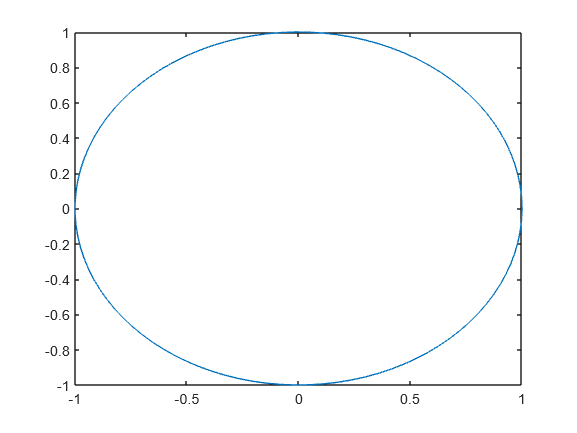

theta = linspace(0,2*pi,100);
x = cos(theta);
y = sin(theta);
plot(x,y);

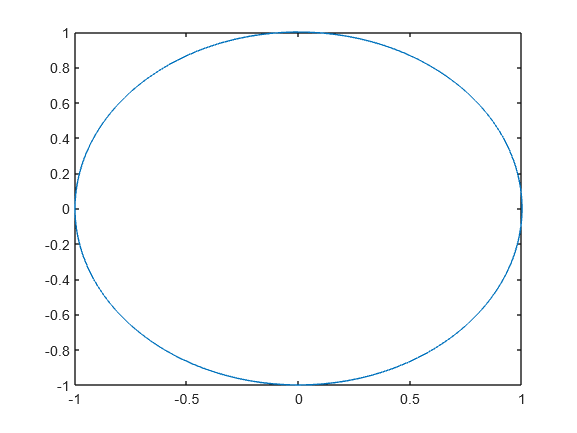

%==========another way=======%
fplot(@(t) cos(t),@(t) sin(t),[0 2*pi])

**Question-4:**  Using MATLAB code, create a 4 × 3 random matrix 𝐴. Also, find its transpose and  multiply both matrices.

**Answer:**

A = round(rand(4,3)*10);
B = A*A';
fprintf("A is\n");

A is


disp(A);

     8     6    10
     9     1    10
     1     3     2
     9     5    10



fprintf("A' is\n");

A' is


disp(A');

     8     9     1     9
     6     1     3     5
    10    10     2    10



fprintf("AxA' is\n");

AxA' is


disp(B);

   200   178    46   202
   178   182    32   186
    46    32    14    44
   202   186    44   206



**Question-5:**  Write a Using MATLAB code that will draw the graph of $\textrm{𝑓}\left(\textrm{𝑥}\right)={\textrm{𝑒}}^{-\textrm{𝑥}/10\;} \textrm{𝑠𝑖𝑛𝑥}$ for 𝑥 between 0 and 20. 

**Answer:**

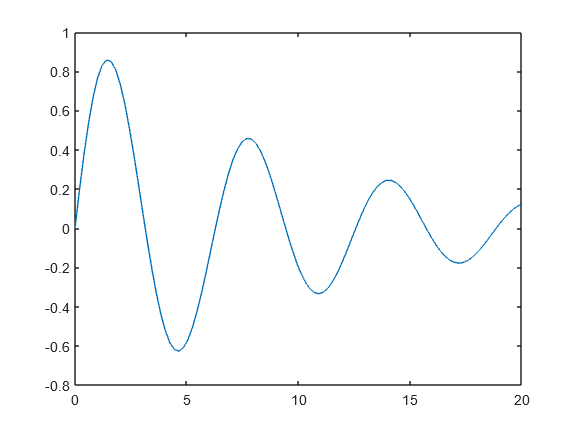

x = linspace(0,20,100);
plot(x, exp(-x/10).*sin(x));

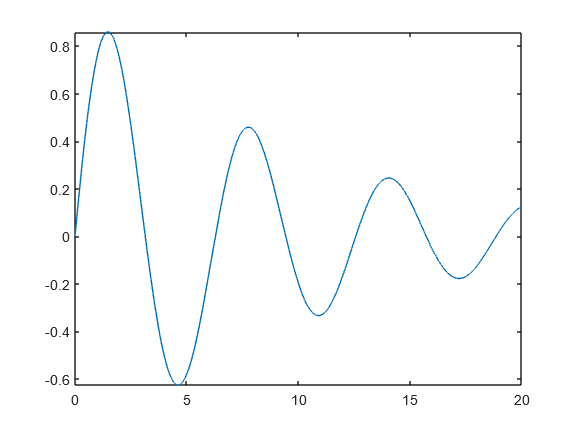

%============using fplot or explot==========%
fplot(@(x) x, @(x) exp(-x/10).*sin(x), [0 20]);

**Question-6:**  Solve following equations or system of equations using solve command and also,  verify result. $\begin{array}{l}
\left(a\right)3{\textrm{𝑥}}^2 -2\textrm{𝑥}-4=0\;\\
\left(b\right){\textrm{𝑥}}^2 -{\textrm{𝑦}}^2 =2,\;\textrm{𝑦}-2\textrm{𝑥}=5\\
\left(c\right)\textrm{𝑠𝑖𝑛𝑥}=2-\textrm{𝑥}\\
\left(d\right){\textrm{𝑒}}^{-x} =\sin \left(x\right)
\end{array}$

**Answer:**

clear all;
syms x y;

%=============solution of (a)============%
eqn1 = 3*x^2 - 2*x -4 == 2;
disp(eqn1);

$$3\,x^{2}-2\,x-4=2$$

fprintf("solution is\n");

solution is


disp(solve(eqn1,x));

$$\left(\begin{array}{c} \frac{1}{3}-\frac{\sqrt{19}}{3}\\ \frac{\sqrt{19}}{3}+\frac{1}{3} \end{array}\right)$$

%========================================%

%=============solution of (b)============%
eqn21 = x^2 - y^2 == 2;
eqn22 = y - 2*x == 5;
[solx,soly] = solve(eqn21, eqn22);
disp(eqn21);

$$x^{2}-y^{2}=2$$

disp(eqn22);

$$y-2\,x=5$$

fprintf("solution is\n");

solution is


disp(solx);

$$\left(\begin{array}{c} -\frac{\sqrt{19}}{3}-\frac{10}{3}\\ \frac{\sqrt{19}}{3}-\frac{10}{3} \end{array}\right)$$

disp(soly);

$$\left(\begin{array}{c} -\frac{2\,\sqrt{19}}{3}-\frac{5}{3}\\ \frac{2\,\sqrt{19}}{3}-\frac{5}{3} \end{array}\right)$$

%========================================%

%=============solution of (c)============%
eqn3 = x + sin(x) -2 == 0 ;
disp(eqn3);

$$x+\sin\left(x\right)-2=0$$

fprintf("solution is\n");

solution is


disp(vpasolve(eqn3));

$$1.1060601577062719106167372970301$$

% vpasolve() use for irrational value
%========================================%

%=============solution of (d)============%
eqn4 = exp(-x) == sin(x);
disp(eqn4);

$${\mathrm{e}}^{-x}=\sin\left(x\right)$$

fprintf("solution is\n");

solution is


disp(vpasolve(eqn4));

$$0.5885327439818610774324520457029$$

% vpasolve() use for irrational value
%========================================%

**Question-7:**  Using MATLAB code, find the zero of the function $\textrm{𝑓}\left(\textrm{𝑥}\right)={\textrm{𝑒}}^{-\textrm{𝑥}} \;-\textrm{𝑠𝑖𝑛𝑥}$near 0.5. 

**Answer:**

clear all;
syms x 
eqn = exp(-x)-sin(x);
disp(eqn);

$${\mathrm{e}}^{-x}-\sin\left(x\right)$$

x0 = 0.5;

x = fzero(@(x) exp(-x)-sin(x),x0);
fprintf("solution is %d",x);

solution is 5.885327e-01

**Question-8:**  Using graphs of $e^{-x}$and $\textrm{sinx}$ and approximate 𝑥-values of the intersecting points find  all the roots of the equation ${\textrm{𝑒}}^{-\textrm{𝑥}} =\textrm{𝑠𝑖𝑛𝑥}$. 

**Answer:**

hold off

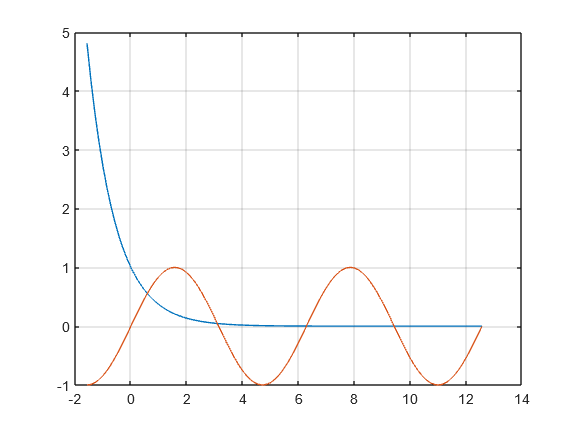

x = linspace(-pi/2,4*pi,100);
plot(x,exp(-x)) ;
grid on;
hold on;
plot(x,sin(x));

syms x;
eqn = exp(-x) == sin(x);
disp(eqn);

$${\mathrm{e}}^{-x}=\sin\left(x\right)$$

disp(vpasolve(eqn));

$$0.5885327439818610774324520457029$$

**Question-9:**  Using ezplot command, get the graph of the function $f\left(\textrm{𝑥}\right)={\textrm{𝑥}}^2 +\textrm{𝑥}+1,\;-2\le \textrm{𝑥}\le 2\ldotp$

**Answer:**

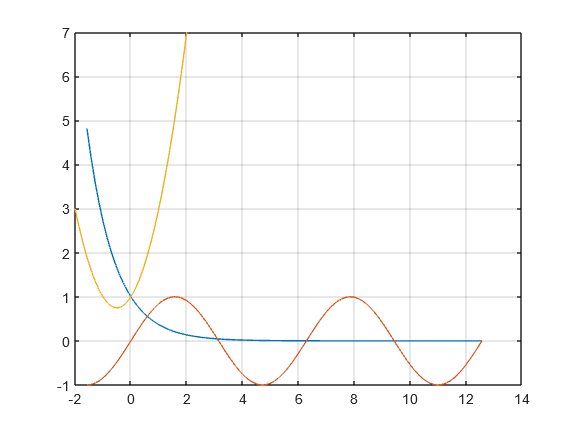

% ezplot(@(x) x.^2+x+1,[-2,2]);
%ezplot is not recommended
fplot(@(x) x.^2+x+1,[-2,2]);

**Question-10:**  Write a MATLAB code that will read 𝑛 and will calculate of the sum of 𝑛 consecutive  numbers.

**Answer:**

n = input("enate value of n");
fprintf("sum of %d consecutive numbers is %d", n , n*(n+1)/2);

sum of 100 consecutive numbers is 5050